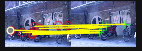

clc; clear; close all;

% Read images
I1 = imread("Images/bikes1.ppm");
I2 = imread("Images/bikes2.ppm");
if size(I1,3)==3, G1 = rgb2gray(I1); else, G1 = I1; end
if size(I2,3)==3, G2 = rgb2gray(I2); else, G2 = I2; end

% Detect keypoints (limit to 100)
pts1 = detectSURFFeatures(G1).selectStrongest(10);
pts2 = detectSURFFeatures(G2).selectStrongest(10);

% Extract descriptors
F1 = my_extract_features_a(G1, pts1.Location);
F2 = my_extract_features_a(G2, pts2.Location);

% Normalize descriptors (important for raw patches)
F1 = double(F1); F2 = double(F2);
F1 = F1 - mean(F1,2);
F2 = F2 - mean(F2,2);
F1 = F1 ./ (sqrt(sum(F1.^2,2)) + 1e-12);
F2 = F2 ./ (sqrt(sum(F2.^2,2)) + 1e-12);

% Match (mutual nearest neighbor)
matches = best_match(F1, F2);   % Kx2: [index_in_1  index_in_2]

% Use numeric Mx2 point locations (avoids showMatchedFeatures size errors)
matchedPoints1 = pts1.Location(matches(:,1), :);
matchedPoints2 = pts2.Location(matches(:,2), :);

% Display
figure;
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, "montage");
title("Matched Features");


%% -------- Local functions (must be at end of script) --------
function [extracted_features] = my_extract_features_a(Img, det_points)
   box_size = 16;
   half = box_size / 2;  % = 8
   num_points = size(det_points, 1);
   extracted_features = zeros(num_points, 128);  % 4x4 cells * 8 bins = 128
   % calculate gradients and directions beforehand
   Gy = fspecial('sobel');
   Gx = Gy';
   Ix = imfilter(double(Img), Gx, 'symmetric');
   Iy = imfilter(double(Img), Gy, 'symmetric');
   G_mag    = sqrt(Ix.^2 + Iy.^2);          % gradient strength
   G_orient = atan2(Iy, Ix);                 % angle in radians, [-pi, pi]
   G_orient(G_orient < 0) = G_orient(G_orient < 0) + 2*pi;  % shift to [0, 2*pi]
   % pad gradient maps
   G_mag    = padarray(G_mag,    [half half], 'symmetric');
   G_orient = padarray(G_orient, [half half], 'symmetric');
   for i = 1:num_points
       % shift coords by 'half' to account for the padding
       x = round(det_points(i,1)) + half;
       y = round(det_points(i,2)) + half;
       % extract 16x16 patch of gradients around this keypoint
       patch_mag    = G_mag(y-half+1:y+half, x-half+1:x+half);
       patch_orient = G_orient(y-half+1:y+half, x-half+1:x+half);
       % loop over 4x4 grid of cells
       bin_width = 2*pi / 8;
       idx = 1;  % tracks where we are in the 128-dim vector
       for cr = 1:4       % cell row (1 to 4)
           for cc = 1:4   % cell col (1 to 4)
               % grab the 4x4 pixel region for this cell
               r_start = (cr-1)*4 + 1;
               r_end   = cr*4;
               c_start = (cc-1)*4 + 1;
               c_end   = cc*4;
               cell_mag    = patch_mag(r_start:r_end, c_start:c_end);
               cell_orient = patch_orient(r_start:r_end, c_start:c_end);
               % build the 8-bin histogram for this cell
               hist_bins = zeros(1, 8);
               for px = 1:numel(cell_mag)
                   % soft binning - split vote between two nearest bins
                   exact_bin = cell_orient(px) / bin_width;
                   lower_bin = floor(exact_bin) + 1;
                   upper_bin = lower_bin + 1;
                   frac = exact_bin - floor(exact_bin);
                   % wrap bin 9 back to bin 1
                   if upper_bin > 8, upper_bin = 1; end
                   hist_bins(lower_bin) = hist_bins(lower_bin) + cell_mag(px) * (1 - frac);
                   hist_bins(upper_bin) = hist_bins(upper_bin) + cell_mag(px) * frac;
               end
               % store this cell's 8 bins into the right spot in the descriptor
               extracted_features(i, idx:idx+7) = hist_bins;
               idx = idx + 8;
           end
       end
   end
end
function d = feature_distance(f, g)
    % Euclidean distance between two 1xD vectors
    diff = double(f) - double(g);
    d = sqrt(sum(diff.^2));
end

function matches = best_match(f, g)
    % threshold_test = 0.75;
    % ratio_test = 0.8;
    match = [];
    size_f = size(f,1);
    size_g = size(g,1);
    for i = 1:size_f
        shortest = inf;
        match_shortest = 0;
        for j = 1:size_g
            d = feature_distance(f(i,:),g(j,:));
            if d < shortest
                shortest = d;
                match_shortest = j;
            end
        end
        
    match = [match; i match_shortest];
    end 
    matches = match;
end
